# Simulating Example 14.5 System

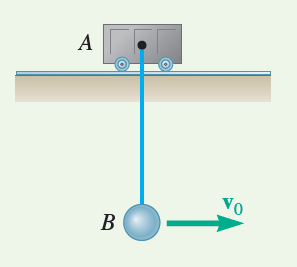

## Modeling

### Cart A


$$\begin{array}{l}
\Sigma F_x =\mathrm{Tsin}\theta =m_a a_a \\
{\mathit{\mathbf{a}}}_a =\frac{\mathrm{Tsin}\theta \;}{m_a }\hat{\mathit{\mathbf{i}}} 
\end{array}$$


### Ball B


$$\begin{array}{l}
\Sigma F_n =T-m_b \mathrm{gcos}\theta =m_b {\left(a_b \right)}_n =m_b \frac{{\left\|{\mathit{\mathbf{v}}}_{\frac{B}{A}} \right\|}^2 }{l}\\
{\mathit{\mathbf{v}}}_{\frac{B}{A}} ={\mathit{\mathbf{v}}}_b -{\mathit{\mathbf{v}}}_a \\
T=m_b \left(\frac{{\left\|{\mathit{\mathbf{v}}}_{\frac{B}{A}} \right\|}^2 }{l}+\mathrm{gcos}\theta \right)\\
\Sigma F_t =-m_b \mathrm{gsin}\theta \;=m_b {\left(a_b \right)}_t \\
{\mathit{\mathbf{a}}}_b =a_n \hat{\mathit{\mathbf{n}}} +a_t \hat{\mathit{\mathbf{t}}} =\frac{{\left\|{\mathit{\mathbf{v}}}_{\frac{B}{A}} \right\|}^2 }{l}\hat{\mathit{\mathbf{n}}} -\mathrm{gsin}\theta \;\hat{\mathit{\mathbf{t}}} 
\end{array}$$


## Simulation

### Assign Properties and Initial Values

% initial time vector and vector of system states
dt = 0.01;
t = 0:dt:5;
Pa = zeros(length(t),2); % makes a nx2 matrix
Pb = zeros(length(t),2);
Va = zeros(length(t),2);
Vb = zeros(length(t),2);
Vba = zeros(length(t),2);
Aa = zeros(length(t),2);
Ab = zeros(length(t),2);

% system properties
L = 1; % length and position of pendulum, meters
theta = 0; % initial angle of pendulum, radians
Ma = 1; % mass of cart A, kg
Mb = 1; % mass of ball B, kg
g = 9.81; % gravity
Bspeed = 1; % m/s

% set initial values of system state

%Pa(i,:) means get/set the row vector of Pa at row i
Pa(1,:) = [0, 0]; % call cart A starting location (0,0)
% Pa(i,j) means get the element of Pa at row i and column j
Pb(1,:) = [Pa(1,1)+L*sin(theta), Pa(1,2)-L*cos(theta)];

Bn = [-sin(theta), cos(theta)]; % unit vector normal to B
Bt = [cos(theta), sin(theta)]; % unit vector tangent to B

Va(1,:) = [0, 0]; % initial velocity of A
Vb(1,:) = Bspeed*Bt;
Vba(1,:) = Vb(1,:) - Va(1,:);

Aa(1,:) = [0, 0];
Ab(1,:) = norm(Vba(1,:))^2/L * Bn - g*sin(theta) * Bt;

### Run Simulation


$$\begin{array}{l}
{\mathit{\mathbf{x}}}_i ={\mathit{\mathbf{x}}}_{i-1} +{\mathit{\mathbf{v}}}_{i-1} \mathrm{dt}+\frac{1}{2}{\mathit{\mathbf{a}}}_{i-1} {\mathrm{dt}}^2 \\
{\mathit{\mathbf{v}}}_i ={\mathit{\mathbf{v}}}_{i-1} +{\mathit{\mathbf{a}}}_{i-1} \mathrm{dt}\\
\\
{\mathit{\mathbf{a}}}_a =\frac{\mathrm{Tsin}\theta \;}{m_a }\hat{\mathit{\mathbf{i}}} \\
{\mathit{\mathbf{a}}}_b =a_n \hat{\mathit{\mathbf{n}}} +a_t \hat{\mathit{\mathbf{t}}} =\frac{{\left\|{\mathit{\mathbf{v}}}_{\frac{B}{A}} \right\|}^2 }{l}\hat{\mathit{\mathbf{n}}} -\mathrm{gsin}\theta \;\hat{\mathit{\mathbf{t}}} 
\end{array}$$


Due to the fact we are taking discrete steps in time, there are numerical errors and the length L of the pendulum will change. We add in a correction term to remove any velocity of ball B that is not tangent to the pendulum.


$$\begin{array}{l}
{\left({\mathit{\mathbf{v}}}_{\frac{B}{A}} \right)}_i ={\left({\mathit{\mathbf{v}}}_{\frac{B}{A}} \right)}_i -\left({\left({\mathit{\mathbf{v}}}_{\frac{B}{A}} \right)}_i \cdot \hat{\mathit{\mathbf{n}}} \right)\hat{\mathit{\mathbf{n}}} \\
{\left({\mathit{\mathbf{v}}}_B \right)}_i ={\left(\;{\mathit{\mathbf{v}}}_A \right)}_i +{\left({\mathit{\mathbf{v}}}_{\frac{B}{A}} \right)}_i 
\end{array}$$


for i = 2:length(t) % start at 2 because already have values for start
    % calculate new position and velocity
    Pa(i,:) = Pa(i-1,:) + Va(i-1,:)*dt + 0.5*Aa(i-1,:)*dt^2;
    Pb(i,:) = Pb(i-1,:) + Vb(i-1,:)*dt + 0.5*Ab(i-1,:)*dt^2;
    Va(i,:) = Va(i-1,:) + Aa(i-1,:)*dt;
    Vb(i,:) = Vb(i-1,:) + Ab(i-1,:)*dt;
    Vba(i,:) = Vb(i,:) - Va(i,:);
    
    %calculate new theta and unit vectors
    theta = atan((Pb(i,1) - Pa(i,1)) / (Pa(i,2) - Pb(i,2)));
    Bn = [-sin(theta), cos(theta)];
    Bt = [cos(theta), sin(theta)];
    
    % add in a correction term due to discrete time steps
    Vba(i,:) = Vba(i,:) - dot(Vba(i,:),Bn)*Bn;
    Vb(i,:) = Va(i,:) + Vba(i,:);
    
    %calculate new acceleration
    T = Mb * (norm(Vba(i,:))^2/L + g*cos(theta));
    Aa(i,:) = [T*sin(theta)/Ma, 0];
    Ab(i,:) = norm(Vba(1,:))^2/L * Bn - g*sin(theta) * Bt;
end

## Visualize Results

% plot two lines to represent the cart and ball
hh1 = plot([Pa(1,1)-0.5,Pa(1,1); Pa(1,1)+0.5,Pb(1,1)],...
    [Pa(1,2), Pa(1,2); Pa(1,2), Pb(1,2)],...
    Marker=".",MarkerSize=20,LineWidth=2);
axis equal
axis([-2*L, 5*L, -L, 0.5*L])
ht = title("Time: " + t(1) + " sec");

% step through the time vector and update the plot 
for id = 1:length(t)
    set(hh1(1), XData=[Pa(id,1)-0.5,Pa(id,1)+0.5],YData=[Pa(id,2),Pa(id,2)]);
    set(hh1(2), XData=[Pa(id,1),Pb(id,1)],YData=[Pa(id,2),Pb(id,2)]);
    set(ht,String="Time: " + t(id) + " sec");
    
    drawnow % forces the plot to update with each loop
end